# LEDS Exam: January 11, 2024

Welcome! 

This is the exam project of the course "*Learning and Estimation of Dynamical Systems M" *(**LEDS**), formely called* "Discrete Time System Identification and Control M" *(**SysID**). Remember to follow the text below very carefully to get the best from your project.

**WARNING: THIS PROJECT IS THOUGHT FOR BOTH THIS COURSE AND THE OLDER ONE, CHECK THE PARTS YOU HAVE TO FULFILL ACCORDING TO THE COURSE YOU TOOK PART TO (SysID or LEDS)**

Your submission must be a **'.zip' **file with name** 'Surname_Name.zip' **(DO NOT USE ACCENTED CHARACTERS NOR SYMBOLS) with the same internal structure as the one provided in the assignment:

- **Functions**

- **Project_Jan11_2024.mlx **

- **Surname_Name.mlx**

where the folder **Functions **will contain all your implemented functions as well as the provided ones to kick start the project.

**Project_Jan11_2024.mlx **(this file) contains the instructions of the project. 

**Surname_Name.mlx **will be your project file in which you will provide your solution together with a detailed explanation of what you did and why you did it. It will serve as your project report as well.

This means you will also have to add a brief description of the functions you implemented to fullfill the project together with the reasoning behind it. 

The project file will also have to follow the instructions provided in the project assignment. 

**The project must be done alone.**

**The project is due for submission by 23:59 of January 18, 2024.**

# Project assignment

clear all
close all
addpath ./Functions;

You will be asked to solve an identification problem in which measurements from the system are available **(1)** and a classification problem were training features are available and try it on a test set **(2)**.

## Exercise 1: Estimation (both SysID and LEDS)

In this exercise you are asked to **estimate** an unknown linear model and **display it**.

To gather system measurements at any point in your code call the function `IdentifyThis.p `with the following inputs:

- Number of samples (`integer`)

N=1500; %set it at a suitable amount 
Nv = 500; %number of samples we use for validation

- Your surname and name with no accents nor special characters (`string`)

Student = 'Davide Corroppoli';

- Your matriculation number (`string`)

Matriculation = '0001075136';

which finally results in

[Measurements] = IdentifyThis(N+Nv, Student, Matriculation);

To collect the measurements it is advised to use this piece of code

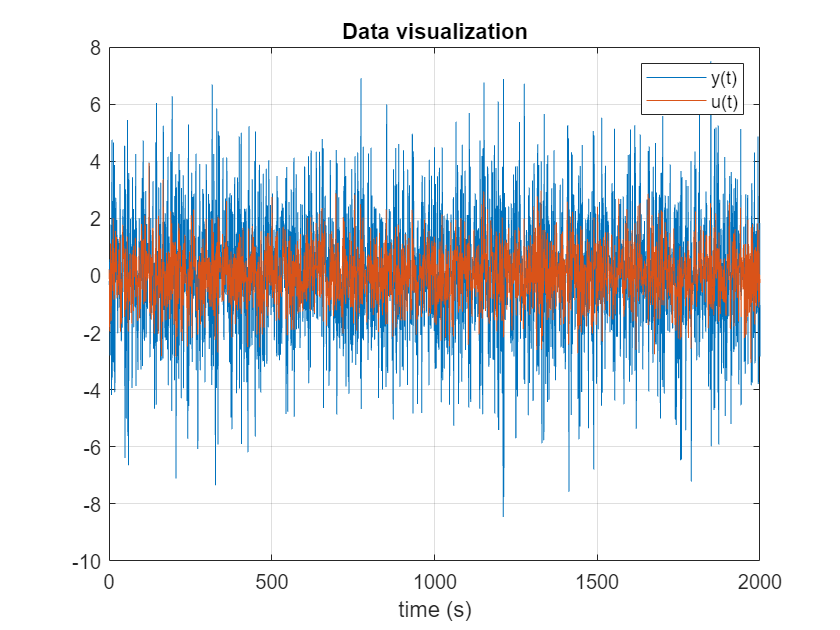

u=Measurements.u;
y=Measurements.y;

%Plot of the data
figure();
plot(1:length(y),y, 1:length(u),u);
grid on;
legend("y(t)", "u(t)");
xlabel("time (s)");
title('Data visualization');

It seems that the output is affected by the input

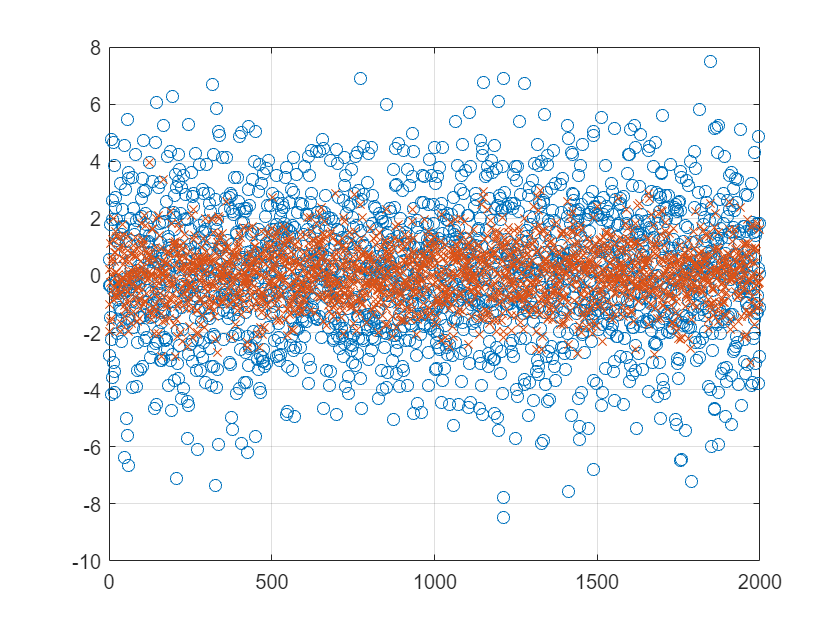


%and now the plot in where we see input and output as series of points
figure();
plot(1:length(y),y, "o", 1:length(u),u, "x");
grid on

Then a plot of a small batch of data to zoom in the process and understand what kind of model could or couldn't be

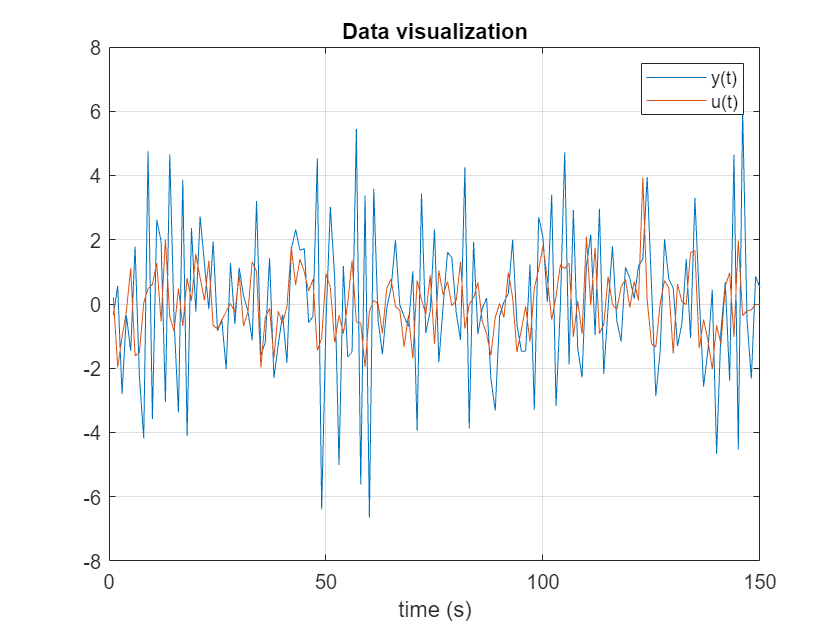

small_plot = int32(N/10);
figure();
plot(1:small_plot,y(1:small_plot), 1:small_plot,u(1:small_plot));
grid on;
legend("y(t)", "u(t)");
xlabel("time (s)");
title('Data visualization');

Then, the identification problem should be solved following the steps below:

- **Understand the model structure**: The provided signals refer to either a ARX or an AR model. You should get the structure straight away from the measurements. Then, display the autocorrelation of the output signal up to lag 10. 

- **Define the required estimation algorithm: **describe the algorithm you plan to use and why and add brief description of the matlab function you implemented accordingly. In this particular case you are asked to implement the recursive version of the estimation algorithm that does not involve the matrix inversion lemma.

- **Estimate the model order: **describe the criteria you plan to use and add brief description of the matlab function you implemented to do that.

- **Validate the model: **describe the criteria with hypothesis testing you plan to use to get model validation and add a description of the matlab functions you implemented to do that. 

ARX models are characterized by an input-output relation $y(t) = \frac{B(z^{-1})}{A(z^{-1})}u(t) + \frac{e(t)}{A(z^{-1})$, while AR models the input is not involved and the error plays the role of an input $y(t) = \frac{e(t)}{A(z^{-1})$. So, ARX models are characterized by an hankel matrix $H = [-H_y(n) \quad H_u(n)]^T \rightarrow \phi = [-y(t-1) \cdots -y(t-n) \; u(t-1) \cdots u(t-n)]^T$

While AR models have $H = H_y \rightarrow \phi(t) = [-y(t-1) \cdots -y(t-n)]^T$. Here below there's an example test to verify the working of the function Hank used to compute the hankel matrix, and the application to both the cases, ARX and AR.

%example with complexity n = 10
n_example = 10;
H_y_ex = Hank(y, n_example, N);
H_u_ex = Hank(u, n_example, N);
Hank_ARX_ex = [-H_y_ex, H_u_ex];
Hank_AR_ex = [-H_y_ex];

From the plot of the data we can at least predict wheter there's an involvement of the input in the output. From the shapes of the signals there seems that input affects the output, so that we would deal with an ARX system. But we can't just rely on a graphical whitness, therefore we need to do also mathematical stuff to prove it.

**Correlation**

Autocorrelation plotting: We plot autocorrelation up to lag 20 of the output 

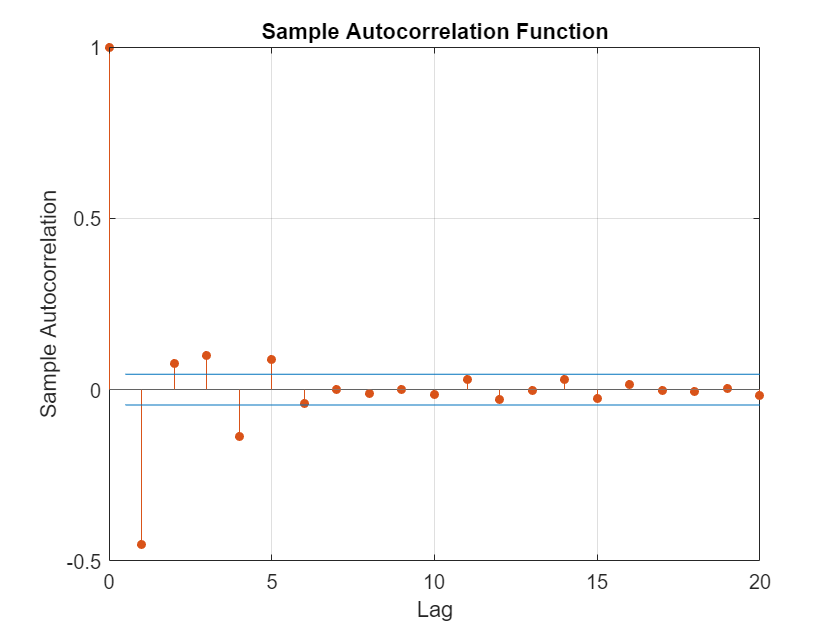

autocorr(y)

It seems it goes to zero asymptotically. And now we compute cross correlation between y and u. If there's correlation we are dealing with ARX models, otherwise just AR

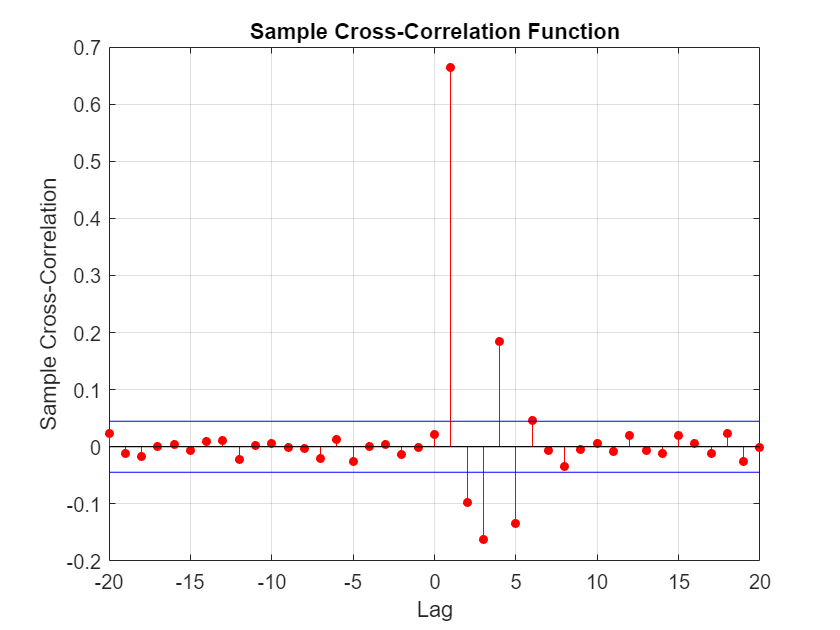

crosscorr(u,y)

%crosscorr(y,u)

It clearly seems that we are dealing with an ARX process, given that u affects so much y. That is visible not only from the cross correlation and autocorrelation plotting with respect to lag but also from the graphics previously plotted in where the shapes in time of u(t) reminds the one of y(t) 

**Estimation algorithm**

Now use the RLS algorithm and test it. Given that we are dealing with an ARX model, the Hankel matrix is $H = [-H_y(n) \quad H_u(n)]^T \rightarrow \phi = [-y(t-1) \cdots -y(t-n) \; u(t-1) \cdots u(t-n)]^T$. The whole RLS procedure is implemented in RLS_ARX function. The idea is to update the estimator theta at each iteration to get the optimal one. We iterate the procedure up to n = 10 (and further if needed), then we compare the result got from the different iterations. To compare them, at each iteration we compute the $\hat y
$ then we use to compute the residuals and then the cost function for each possible order of the model.

total_n = 10;
cost = zeros(total_n, 1);
for i = 1:total_n
    theta = RLS_ARX(y(1:N), u(1:N), i);
    H_u = Hank(u(1:N),i, N);
    H_y = Hank(y(1:N),i, N);
    H_ARX_est = [-H_y, H_u]';
    y_est = theta'*H_ARX_est;
    
    residual = y_est' - y(i+1:N);
    cost(i) = residual'*residual/N;
end 

plot(cost)
title("Cost function")

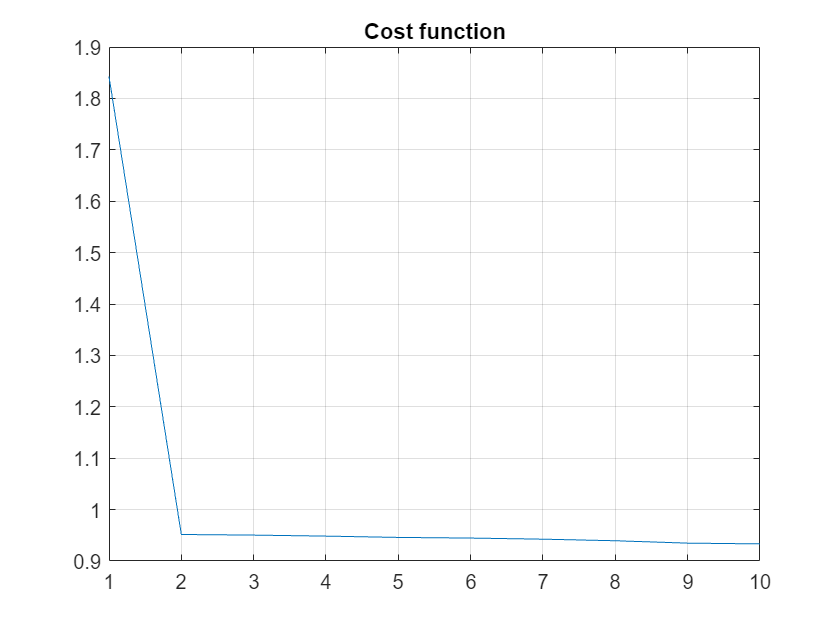

grid on

**Order estimation**

If we look at the cost function, it seems that the second order model approximates well the system according to flexibility and parsimony principle but let's provide the F-test and the MDL test with the cost functions got. For F-test we compare model with consecutive complexity. In ARX models $p = 2n
$ so the difference between two models, one of complexity n and the other of complexity n+1 is always $p_{n+1}-p_n = 2
$. F-test deal with a test quantity $x = \frac{J(\hat\theta_N^1)-(\hat\theta_N^2)}{(\hat\theta_N^2)}
$ where the apex 1 represent the model class with lower complexity and the apex 2 represent the model class with higher complexity. Indicatively, if x is large we take the high order complexity model, if x is small we keep the low complexity one (parsimony principle). But to be precise we have to provide the statistical test choosing a value $\alpha
$. Instead with MDL we just pick the lowest value in general of the criterion, we don't compare different complexities. $MDL = N \; log\,J(\hat \theta_N) + 2p \; log\,N$. MDL is a so called criteria with complexity term because it penalizes $J(\hat \theta_N) $ with increasing orders. We pick MDL as a reference for criteria with complexity, in this way we use a criteria with complexity (MDL) and another "without" complexity (the F-test). As before we iterate in a for loop the various order of complexity and then we analyze the results with the help of plot and see if they match. The calculus and the operation done in these two different tests are provided in the functions mdl and ftest. To keep the simmetry between these two methods I made them in a way that they take the same argument as an input

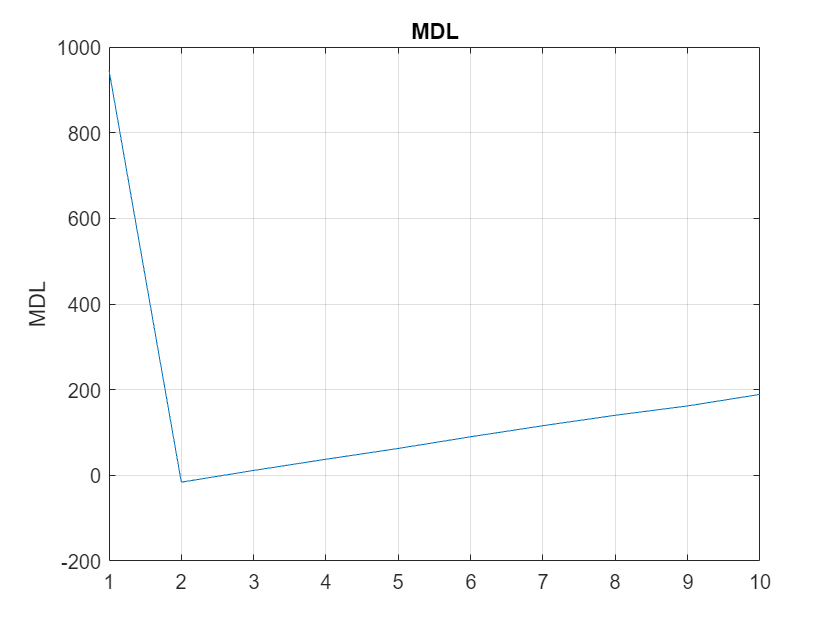

MDL = zeros(total_n,1);
Ftest = zeros(total_n,1);
for k=1:total_n
    MDL(k) = mdl(N, cost, k);
    if k > 1
        Ftest(k) = ftest(N, cost, k);
    end
end

plot(MDL)
title("MDL")
ylabel("MDL")
grid on

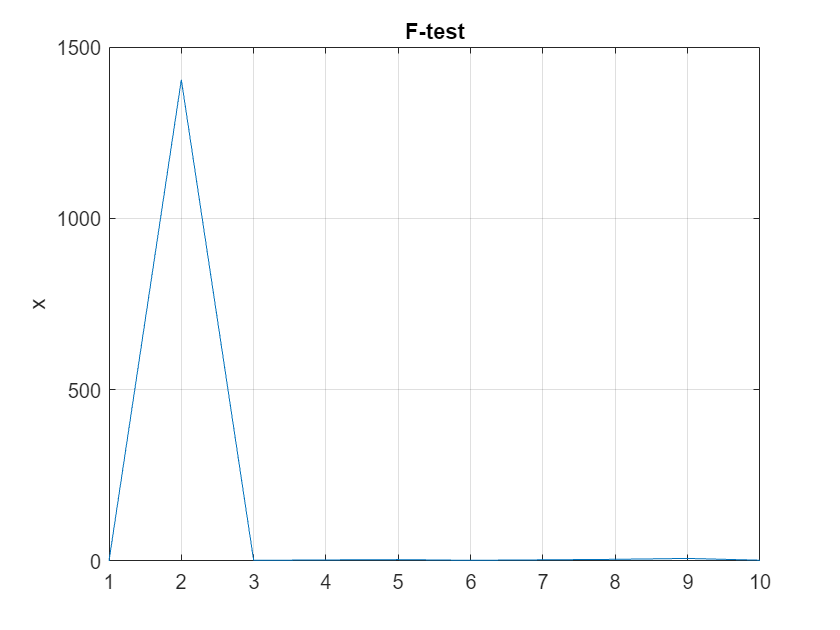

plot(Ftest)
title("F-test")
ylabel("x")
grid on

min(MDL)

ans = -15.9413

Ftest(2)

ans = 1.4044e+03

Ftest(3)

ans = 1.8895

It clearly looks like a second order complexity ARX model. For sake of completeness we provide also the statistical test with the F-test between first an 2nd order to take second order and with 2nd and 3rd order to keep the second order. Considering $\alpha = 0.05$, we have $n= 1, p_1= 2, n= 2, p_2 = 4 \rightarrow \chi^2_{0.05} (p_2-p_1 = 2)= 5.99$, we get a value in the order of $10^3$ so we take $M_{p_2}$. And then $n = 2, p = 4 \rightarrow \chi^2_{0.05} = 5.99, \quad 0 \approx 8 <? \, 5.99 \rightarrow n = 2$ is good. Actually, most of the time we satisfy this requirement, but there have been trials in which x was bigger than 6 

**Validation**

Now, we are going to validate the selected model of order 2. We provide the test of whiteness with the residuals. We consider a statistical hypotesis test in where the null hypotesys is that $\epsilon(t, \hat\theta_N)
$ is a zero mean white process. We utilize a function residual_autocorr to compute the autocorrelation for a given lag $\hat r_\epsilon (\tau) = \frac{1}{N}\sum^{N-\tau}_{t = 1} \epsilon(t)\epsilon(t-\tau) $, and then we find the vector $\hat r_\epsilon = [\hat r_\epsilon(1) \cdots \hat r_\epsilon(m)]^T$ containing all the autocorrelations of lag different to 0. If $H_0$ is true then $\hat r_\epsilon(0) \rightarrow_{N \rightarrow \infty} \sigma^2_w$ and $\hat r_\epsilon(\tau) \rightarrow_{N \rightarrow \infty} 0$. We have the test variable $x = N \frac{\hat r_\epsilon^T \hat r_\epsilon }{\hat r_\epsilon^2(0)} \rightarrow_{N \rightarrow \infty} \approx\chi^2(m)$ or the normalized one $\hat \lambda(\tau) = \frac{\hat r_\epsilon (\tau)}{\hat r_\epsilon (0) $ that allows to perform a set of m gaussian tests. With $\alpha = 0.05$ if we have a set of tests $H_0^\tau : | \hat \lambda (\tau)| \leq \frac{1.96}{\sqrt N}$ and then we finally accept it if the number of failed test over the number of test is less or equal than $\alpha \rightarrow \frac{\overline{m}}{m} \leq \alpha = 0.05 \rightarrow H_0$. But first we have to start by recomputing theta, the Hankel matrix and the residuals for the order found.

minMDL = min(MDL);
order = find(MDL == minMDL); %The selected order we will use from now on is the indices of the min of MDL (it will be 2 almost surely)
H_y = Hank(y(1:N), order, N);
H_u = Hank(u(1:N), order, N);
Hankel = [-H_y, H_u]';
theta = RLS_ARX(y(1:N), u(1:N), order);
y_est = theta'*Hankel;
residual = y_est' - y(1+order:N);

And now finally we can start the test

m = 20;
r0 = residual_autocorr(residual, 0);
reps = zeros(m,1);
lambda = zeros(m,1);
counter = 0; %keep track of how many tests are failed
for j=1:m
    reps(j) = residual_autocorr(residual, j);
    lambda(j) = reps(j)/r0; %normalized test quantities
    if abs(lambda(j)) > 1.96/sqrt(N)
        counter = counter +1; %increase number of test failed
    end

end
disp("Number of failed test")

Number of failed test


disp(counter)

     2



if counter >= 2
    disp("Whiteness test failed")
else 
    disp("Whiteness test succesful")
end

Whiteness test failed


**Cross validation**

We have validated our model. To further validate it we can provide also the cross validation on the data that we previously reserved to validation and not used for estimation (the Nv samples). Basically we use our estimator $\hat \theta$ to get $\hat y = \phi^T(t) \hat \theta_N$, we find the residuals $\epsilon = y - \hat y
$ and we provide whiteness test on these new residuals with an analog procedure to the one before with the function Whiteness_test that provide the whiteness test and return the number of failed test with normalized autocorrelations, and print wheter the test has been successful or not. First we have to find the new Hankel matrix. For cross correlation we will consider data of u and y ranging from N to N+Nv (end).

Cross_Hy = Hank(y(N+1:end), order, Nv);
Cross_Hu = Hank(u(N+1:end), order, Nv);
Cross_Hankel = [-Cross_Hy, Cross_Hu]';
Cross_y_est = Cross_Hankel'*theta;
Cross_residuals = y(N+1+order:end) - Cross_y_est;

Failed_crosstest = Whiteness_test(Cross_residuals)

    "Whiteness test succesful"



Failed_crosstest = 0

Just for sake of curiosity print y and the estimated one with the validation data

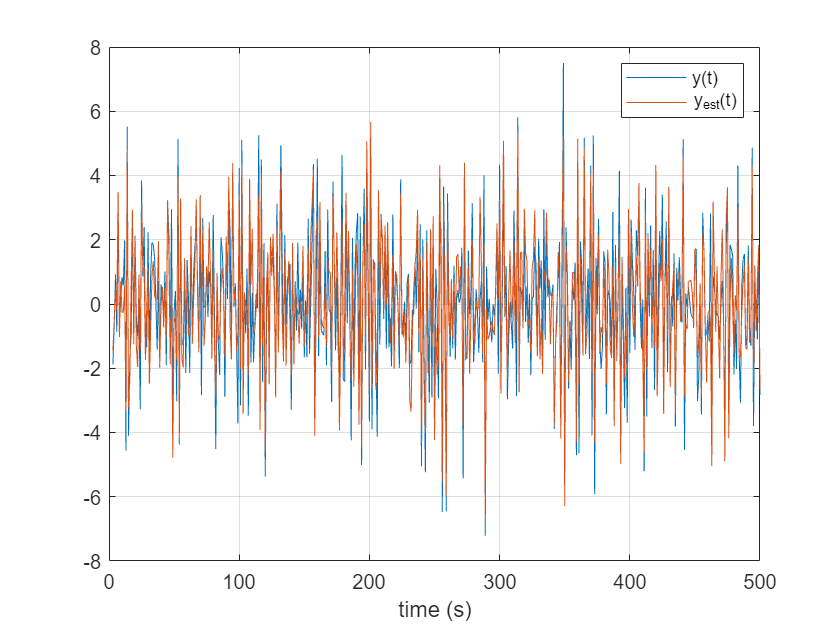

plot(order+1:Nv,y(N+1+order:end), order+1:Nv,Cross_y_est);
legend("y(t)", "y_{est}(t)");
xlabel("time (s)");
grid on

### ONLY IN THE CASE YOU ARE A STUDENT FROM THE OLD SysID COURSE (Not LEDS)

- **Provide your model estimation statistics: **Make use of a Monte Carlo simulation to get your algorithm model estimation statistics to obtain the resulting mean values, standard deviations and variances of the model parameters and show your results.

**NOTICE: **A Monte Carlo simulation to get the statistics of your estimation may be implemented as the following (this is just an example, don't take it into account as an "undisputed truth"). Remember to uncomment it before the use.

% nExperiments = 1000;
% 
% for i=1:nExperiments
%     [Measurements] = IdentifyThis(N,Student,Matriculation);
%     u=Measurements.u;
%     y=Measurements.y;
%     
%     theta(:,i)=mySuperAmazingIdentificator(u,y,n);    
% end

Then to get the statistics

% ThetaMean=mean(theta');
% ThetaSTD=std(theta');
% ThetaVar=var(theta');

And display them in some way.

## Exercise 2: Classification (Only for LEDS students)

In this exercise you are asked to create a classificator from a training set and test it on a new test set..

To gather your set of labelled features at any point in your code call the function `ClassifyThoses.p `with the following inputs:

- Number of samples (`integer`)

N=1000; %set it at a suitable amount 

- Your surname and name with no accents nor special characters (`string`)

Student = 'Davide Corroppoli';

- Your matriculation number (`string`)

Matriculation = '0001075136';

which finally results in

[FeatureSet] = ClassifyThose(N,Student,Matriculation);

To collect the set it is advised to use this piece of code

Utrain  = FeatureSet.Utrain;
Ytrain  = FeatureSet.Ytrain;
Utest   = FeatureSet.Utest;
Ytest   = FeatureSet.Ytest;

Then, the classification problem should be solved following the steps below:

- **Understand the feature set in space**: The provided training features are scattered in space in a particular (geometrical) way. Understand it and use it to define a "refined" feature set if needed. (Plotting them may result useful). Notice that the training set distribution in space changes at every run of the function, however the boundary shape is always the same. This can be handled easily in a well thought program.

- **Define the required classification algorithm: **describe the algorithm you plan to use and why and add brief description of the matlab function you implemented accordingly. 

- **Verify and test your classificator: **verify the obtained classificator on the provided training set and compute the related classification error. Then, try your classificator on the test set and plot your results together with the classification error on the test set.

Remember to add a brief description of the matlab function you implemented accordingly.

**P.S.: **Remember that $\varphi(t)=\left[\begin{array}{l}
1 & \bar u(t)
\end{array}\right]^{T}$ in the case of complex curves.

**P.S.: **Remember that in the case of features representing **more than two classes** you can train a classifier that divides one class with respect to all the others and you can compute one per each class against all the others. In this context, the final prediction is the maxumum value obtianed by applying each of the one-vs-the-rest classifiers to a new set of features. **If this is the case, do not plot every single 1vs1 boundary and prediction, just create the final plot with all the boundaries and the relative classes.**

Write an organic **Surname_Name.mlx **file contaning both the explanation and coding that follows the above steps of **BOTH** exercises. This will also be your final project report. Remeber to read carefully the exam description with the submission rules.


%Let's find how many classes there are 
num_classes = max(Ytrain)

num_classes = 5

And then plot all the data

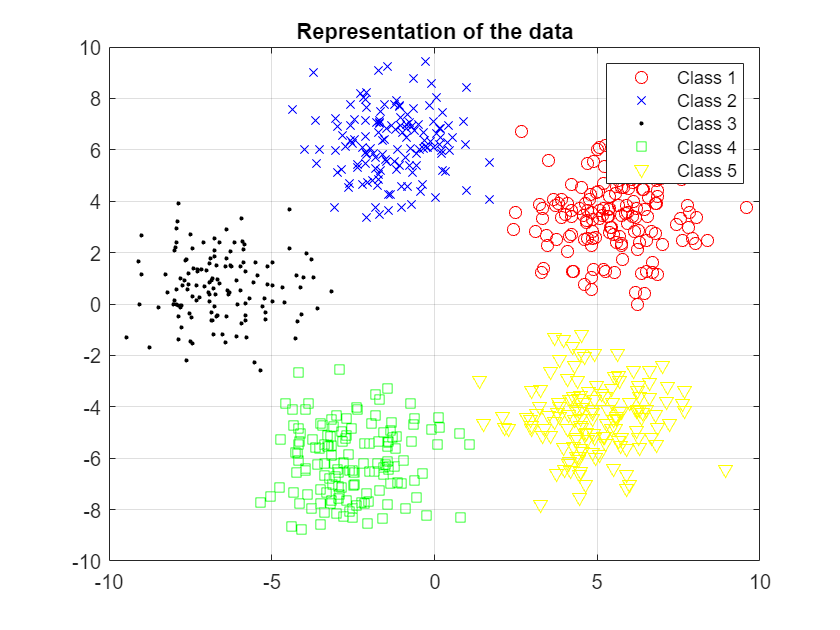

figure(1)
plot(Utrain(find(Ytrain==1),1),Utrain(find(Ytrain==1),2),'r o');
hold on
plot(Utrain(find(Ytrain==2),1),Utrain(find(Ytrain==2),2),'b x');
hold on 
plot(Utrain(find(Ytrain==3),1),Utrain(find(Ytrain==3),2),'.k');
hold on
plot(Utrain(find(Ytrain==4),1),Utrain(find(Ytrain==4),2),'g square');
hold on
plot(Utrain(find(Ytrain==5),1),Utrain(find(Ytrain==5),2),'yellow v');
title("Representation of the data");
legend("Class 1", "Class 2", "Class 3", "Class 4", "Class 5");
grid on

**Multiclass one vs all approach**

Multiclass problem is splitted into M (5 in this case) two-classes problems, involving the class $C_i
$ and $\overline C_i = [C_1,\cdots , C_{i-1}, C_{i+1}, \cdots, C_M]$. The input, as written before, is assignd to the class that has the maximum value in posterior probability. In this situation we can't assume linear decision boundary, but we evaluate a third order polynomial boundary or a quadratic one: the third order one is represented by$\varphi(t)=\left[\begin{array}{l}
1 & \bar u(t)
\end{array}\right]^{T} = [ 1 \; u_1(t) \; u_2(t) \; u_1(t)u_2(t) \; u_1^2(t) \; u_2^2(t) \; u_1(t)u_2^2(t) \; u_1^2(t)u_2(t) \; u_1^3(t) \; u_2^3(t)]^T$ and 10 coefficients $\theta = [\beta_0 \cdots \beta_9]^T$, the quadratic one one by $\varphi(t)=\left[\begin{array}{l}
1 & \bar u(t)
\end{array}\right]^{T} = [ 1 \; u_1(t) \; u_2(t) \; u_1(t)u_2(t) \; u_1^2(t) \; u_2^2(t)]^T$ and 10 coefficients $\theta = [\beta_0 \cdots\beta_5]^T$. In both cases of course $z(t) = \overline\phi(t) \theta
$. For each of the five classes we repeat the same procedure: we find the estimate $\hat \theta_N
$ maximizing the posterior probability of the observation $Y = [y(1) \cdots y(N)]^T$ with the maximum likelihood estimation. Modeling the posterior probability as sigmoid function for a generic class i we get $P(C_i|u(t)) = f(z(t)) = \frac{e^{z(t)}}{1+e^{z(t)}} \quad P(\overline C_i|u(t)) = 1 - f(z(t)) = \frac{1}{1+e^{z(t)}} \quad z(t) = log \frac{ P(C_i|u(t)) }{P(\overline C_i|u(t))} = log \frac{f(z)}{1-f(z)}$. We get a log likelihood function $log (P(Y|\theta) = \sum^N_{t=1}[ y(t) \, log \, f(z(t)) + (1-y(t))\, log\,(1-f(z(t)))]$ and we minimize its negative (that become the cost function $J(\theta) = -logP(Y|\theta)$) by using the Newton Raphson method $\hat \theta^{k+1} = \hat \theta^k- \eta^k(\phi^TW(\theta) \phi)^{-1} \phi^T(F(\theta)-Y)$. Then to classify the input we compute $\hat z (t) = \phi^T(t)\hat \theta$ that we use to compute $f(\hat z(t)) = \hat P(C_i|u(t)) = \frac{e^{\hat z}}{1+e^{\hat z}}$ then compare all the $\hat P(C_i|u(t))$ probabilities and assign the input to the most likely class.

order_u = 2; %we start evaluating th quadratic one, if it's not enough precise we shift to third order polynomial
if order_u == 2
    p_order = 6;
elseif order_u == 3
    p_order = 10;
end

thetaest = zeros(p_order, 1); %initialize theta
eta = 1; %stepsize


Now we change the observation to make them suitable to a one vs all problem. For each class we transform the value in which it 's classified into a one and other value to zero $y(t) = 3 \rightarrow y_3 = 1, \; y_{\overline 3} = 0$. In the end we got a matrix ybin with N rows and 5 columns. This matrix has a 1 per row, in the postion corresponding to the class of the observation, and zero in the other four positions.

y1 = Ybin(Ytrain, 1);
y2 = Ybin(Ytrain, 2);
y3 = Ybin(Ytrain, 3);
y4 = Ybin(Ytrain, 4);
y5 = Ybin(Ytrain, 5);
ybin = [y1, y2, y3, y4, y5]; 

Now let's create the function Phi with the generic second order polynomial input form. We create an apposite function to do that: Create_phi.

u1 = Utrain(:,1);
u2 = Utrain(:,2);
PHI = Create_phi(u1,u2,2);

Then start the iteration with NR method. In which we need to compute the hessian and the gradient of J through apposite function. We repeat the procedure for all of the five classes. 

theta = zeros(p_order, num_classes);

max_iter = 50; %set max number of iteration
J = zeros(max_iter, num_classes);
for i = 1:num_classes
    for k = 1:max_iter
        z = PHI*theta(:,i);
        Jd = grad_J(z, ybin(:,i), PHI);
        Jdd = Hessian_J(z, PHI);
        theta(:,i) = theta(:,i) - eta*Jdd\Jd;
        J(k, i) = ComputeCost(z,ybin(:,i));
    end
end

We don't explicitely use a stopping criterion, because it would be difficult to identify one that could fit all five variables. There could be cases in which for one class I got the right parameters and then stopping criterion impone me to stop but for other classes couldn't be satisfying. We just set up a good number of max iteration. If we are not satisfied with this number we can increase it. Now we have theta for all five variables so we can plot the quadratic (or cubic if we set order_u = 3) boundaries. Actually plotting the boundaries in the $u_1 -u_2$ plane it's not so easy, I use function ezplot to accomplish it. 

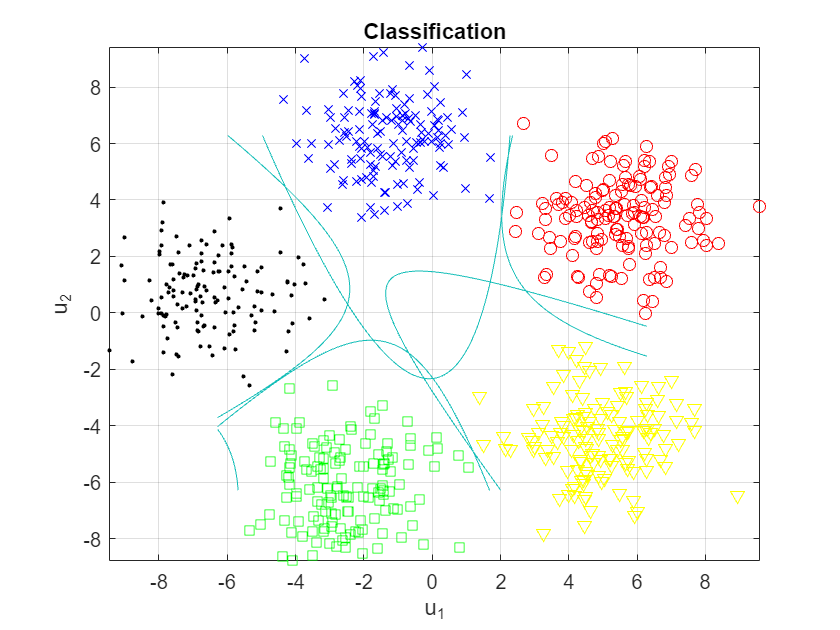


figure(2)
syms u1 u2

plot(Utrain(find(Ytrain==1),1),Utrain(find(Ytrain==1),2),'r o');
hold on
zbound = theta(1, 1) + u1*theta(2,1) + u2 * theta(3,1) + u1*u2* theta(4,1) + u1^2 * theta(5,1) + u2^2 *theta(6,1);
ezplot(zbound);
hold on

plot(Utrain(find(Ytrain==2),1),Utrain(find(Ytrain==2),2),'b x');
hold on
zbound = theta(1, 2) + u1*theta(2,2) + u2 * theta(3,2) + u1*u2* theta(4,2) + u1^2 * theta(5,2) + u2^2 *theta(6,2);
ezplot(zbound);
hold on

plot(Utrain(find(Ytrain==3),1),Utrain(find(Ytrain==3),2),'. k');
hold on
zbound = theta(1, 3) + u1*theta(2,3) + u2 * theta(3,3) + u1*u2* theta(4,3) + u1^2 * theta(5,3) + u2^2 *theta(6,3);
ezplot(zbound);
hold on

plot(Utrain(find(Ytrain==4),1),Utrain(find(Ytrain==4),2),'g square');
hold on
zbound = theta(1, 4) + u1*theta(2,4) + u2 * theta(3,4) + u1*u2* theta(4,4) + u1^2 * theta(5,4) + u2^2 *theta(6,4);
ezplot(zbound);
hold on

plot(Utrain(find(Ytrain==5),1),Utrain(find(Ytrain==5),2),'v yellow');
hold on
zbound = theta(1, 5) + u1*theta(2,5) + u2 * theta(3,5) + u1*u2* theta(4,5) + u1^2 * theta(5,5) + u2^2 *theta(6,5);
ezplot(zbound);
grid on
title("Classification")
hold off

**Test set**

Now let's see how the estimator behaves with the test set. The input is assigned to the class with the class with the largest posterior probability $k = argmax \, \hat P(C_i|u(t)) \quad i = 1,2,\cdots, M
$. We have to create a new Phi matrix,  then we can compute posterior probability$\hat P(C_1|u(t)) = \frac {e^{\hat z}}{1+ e^{\hat z}} \quad \hat z = \phi^T(t) \hat \theta
$, the procedure must be repeated for all the 5 classes, then we compare the probabilities and assign the input to the class. Actually we can exploit the fact that the sigmoid function is a monotonous function so finding the max of $\frac {e^z}{1+e^z}$ is equivalent to find the max z(t). We compute 5 $\hat z(t)
$ one for each class, represented by matriz Z (zhat in the code), then finding the max value for each row we find the index and so the class where to assign the input. That is implemented in the function Classifier. In the end, with the function Misclassifier we compute the error rate  

u1_test = Utest(:,1);
u2_test = Utest(:, 2);
PHI_test = Create_phi(u1_test, u2_test, order_u);
Ntest = length(Utest);
zhat = PHI_test*theta;
Ytest_found = Classifier(zhat);

Now compute how the error rate with the misclassifier function. It basically compute the error rate

Error_rate = Misclassifier(Ytest_found, Ytest) 

Error_rate = 0

And plot the result

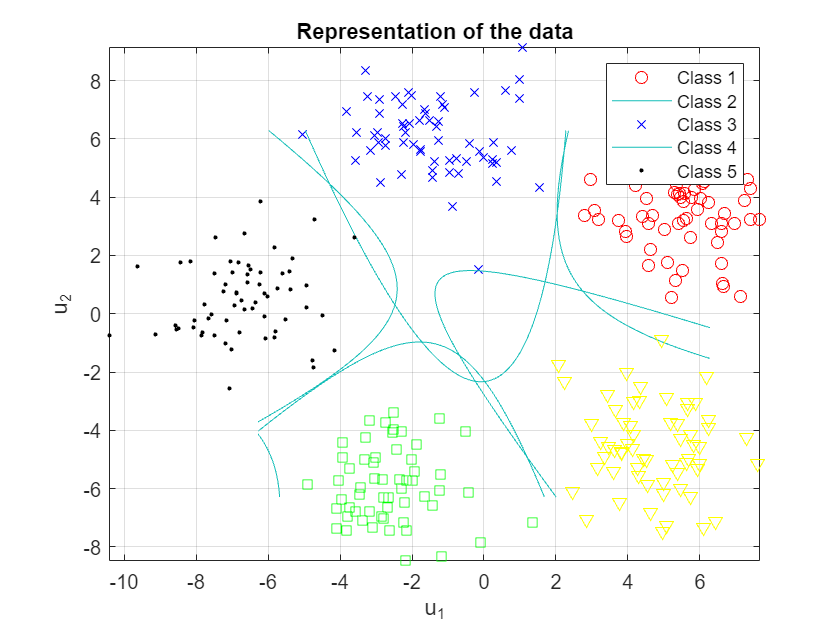

figure(3)
plot(Utest(find(Ytest_found==1),1),Utest(find(Ytest_found==1),2),'r o');
hold on
zbound = theta(1, 1) + u1*theta(2,1) + u2 * theta(3,1) + u1*u2* theta(4,1) + u1^2 * theta(5,1) + u2^2 *theta(6,1);
ezplot(zbound);
hold on
plot(Utest(find(Ytest_found==2),1),Utest(find(Ytest_found==2),2),'b x');
hold on 
zbound = theta(1, 2) + u1*theta(2,2) + u2 * theta(3,2) + u1*u2* theta(4,2) + u1^2 * theta(5,2) + u2^2 *theta(6,2);
ezplot(zbound);
hold on
plot(Utest(find(Ytest_found==3),1),Utest(find(Ytest_found==3),2),'.k');
hold on
zbound = theta(1, 3) + u1*theta(2,3) + u2 * theta(3,3) + u1*u2* theta(4,3) + u1^2 * theta(5,3) + u2^2 *theta(6,3);
ezplot(zbound);
hold on
plot(Utest(find(Ytest_found==4),1),Utest(find(Ytest_found==4),2),'g square');
hold on
zbound = theta(1, 4) + u1*theta(2,4) + u2 * theta(3,4) + u1*u2* theta(4,4) + u1^2 * theta(5,4) + u2^2 *theta(6,4);
ezplot(zbound);
hold on
plot(Utest(find(Ytest_found==5),1),Utest(find(Ytest_found==5),2),'yellow v');
zbound = theta(1, 5) + u1*theta(2,5) + u2 * theta(3,5) + u1*u2* theta(4,5) + u1^2 * theta(5,5) + u2^2 *theta(6,5);
ezplot(zbound);
grid on
title("Representation of the data");
legend("Class 1", "Class 2", "Class 3", "Class 4", "Class 5");
hold off

Personal note: even if matlab discourage the use of ezplot as function it seems that fullfils its task. It just gives problems when I try to give more inputs, so it doesn't allow to change the color of the boundaries that remain the same for all the boundaries.

**On a new dataset**

In the end, let's create a new dataset and verify the performance of the classifier on this new dataset

Nd = 1000;
[NewFeatureSet] = ClassifyThose(Nd,Student,Matriculation);
Unew = NewFeatureSet.Utrain;
Ynew = NewFeatureSet.Ytrain;

u1_new = Unew(:,1);
u2_new = Unew(:,2);
PHI_new = Create_phi(u1_new, u2_new, 2);
z = PHI_new*theta;
Ynew_found = Classifier(z);
New_error_rate = Misclassifier(Ynew_found, Ynew)

New_error_rate = 0

And in the end plot also this new classification with new data and our estimator 

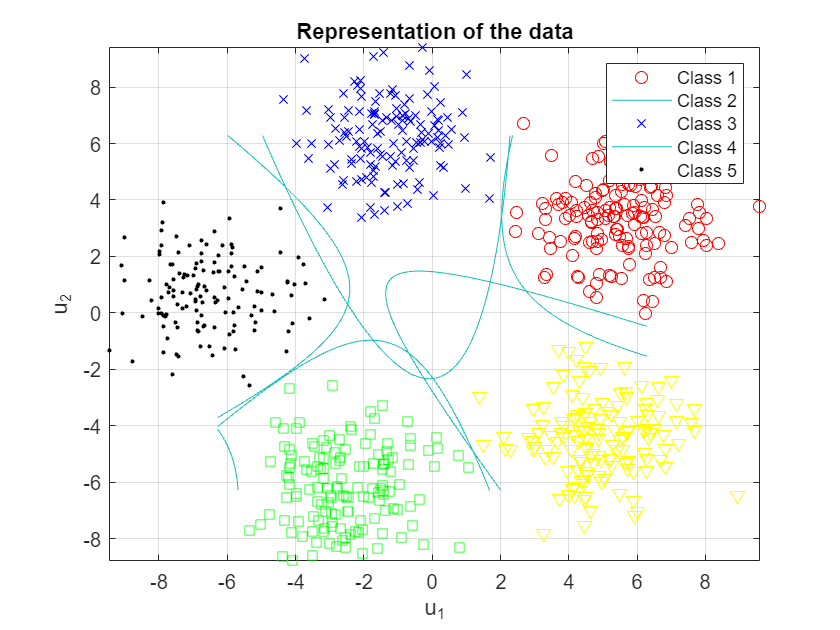

figure(4)
plot(Unew(find(Ynew_found==1),1),Unew(find(Ynew_found==1),2),'r o');
hold on
zbound = theta(1, 1) + u1*theta(2,1) + u2 * theta(3,1) + u1*u2* theta(4,1) + u1^2 * theta(5,1) + u2^2 *theta(6,1);
ezplot(zbound);
hold on
plot(Unew(find(Ynew_found==2),1),Unew(find(Ynew_found==2),2),'b x');
hold on 
zbound = theta(1, 2) + u1*theta(2,2) + u2 * theta(3,2) + u1*u2* theta(4,2) + u1^2 * theta(5,2) + u2^2 *theta(6,2);
ezplot(zbound);
hold on
plot(Unew(find(Ynew_found==3),1),Unew(find(Ynew_found==3),2),'.k');
hold on
zbound = theta(1, 3) + u1*theta(2,3) + u2 * theta(3,3) + u1*u2* theta(4,3) + u1^2 * theta(5,3) + u2^2 *theta(6,3);
ezplot(zbound);
hold on
plot(Unew(find(Ynew_found==4),1),Unew(find(Ynew_found==4),2),'g square');
hold on
zbound = theta(1, 4) + u1*theta(2,4) + u2 * theta(3,4) + u1*u2* theta(4,4) + u1^2 * theta(5,4) + u2^2 *theta(6,4);
ezplot(zbound);
hold on
plot(Unew(find(Ynew_found==5),1),Unew(find(Ynew_found==5),2),'yellow v');
hold on
zbound = theta(1, 5) + u1*theta(2,5) + u2 * theta(3,5) + u1*u2* theta(4,5) + u1^2 * theta(5,5) + u2^2 *theta(6,5);
ezplot(zbound);
grid on
title("Representation of the data");
legend("Class 1", "Class 2", "Class 3", "Class 4", "Class 5");
grid on